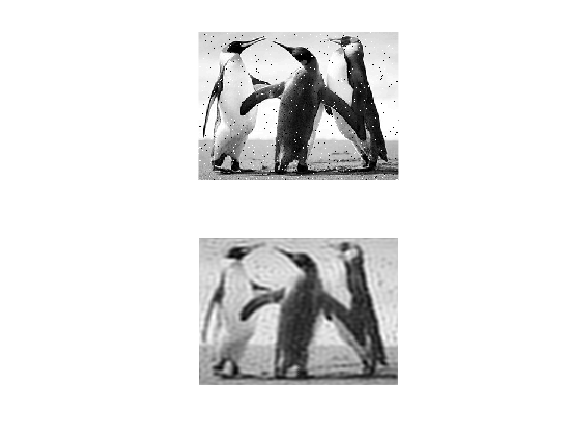

%Ideal Low Pass Filters

input_image = imread('input17.png');
  
[M, N] = size(input_image);
  
FT_img = fft2(double(input_image));
D0 = 30; 
u = 0:(M-1);
idx = find(u>M/2);
u(idx) = u(idx)-M;
v = 0:(N-1);
idy = find(v>N/2);
v(idy) = v(idy)-N;
[V, U] = meshgrid(v, u);
D = sqrt(U.^2+V.^2);
H = double(D <= D0);
G = H.*FT_img; 
output_image = real(ifft2(double(G)));

subplot(2, 1, 1), imshow(input_image),
subplot(2, 1, 2), imshow(output_image, [ ]);

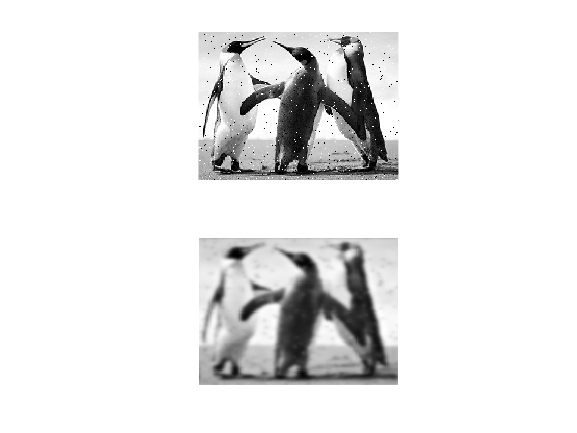


%Butterworth Low Pass Filters
[M, N] = size(input_image);
  
FT_img = fft2(double(input_image));
  
n = 2;

D0 = 20;
  
u = 0:(M-1);
v = 0:(N-1);
idx = find(u > M/2);
u(idx) = u(idx) - M;
idy = find(v > N/2);
v(idy) = v(idy) - N;
  
[V, U] = meshgrid(v, u);

D = sqrt(U.^2 + V.^2);
  
% determining the filtering mask
H = 1./(1 + (D./D0).^(2*n));
G = H.*FT_img;
  
output_image = real(ifft2(double(G))); 
    
subplot(2, 1, 1), imshow(input_image), 
subplot(2, 1, 2), imshow(output_image, [ ]);

%Gaussian Low Pass Filters

  
[M, N] = size(input_image);
   
FT_img = fft2(double(input_image));
  
D0 = 30; 
u = 0:(M-1);
idx = find(u>M/2);
u(idx) = u(idx)-M;
v = 0:(N-1);
idy = find(v>N/2);
v(idy) = v(idy)-N;
  
[V, U] = meshgrid(v, u);

D = sqrt(U.^2+V.^2);

H = double(D <= D0);
  

G = H.*FT_img;

output_image = real(ifft2(double(G)));

subplot(2, 1, 1), imshow(input_image),
subplot(2, 1, 2), imshow(output_image, [ ]);

% Sharpening 

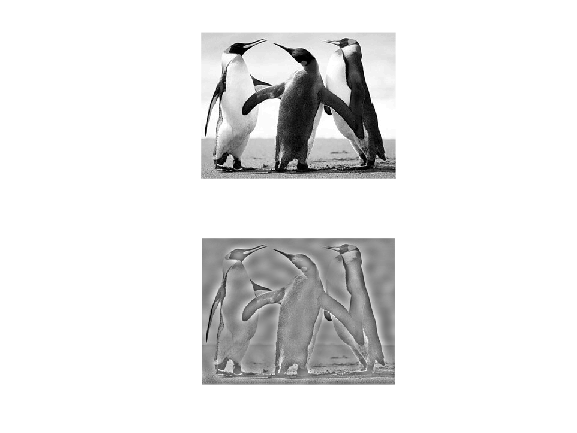

%Ideal Highpass Filter in Image Processing
input_image = imread('input14.png');
[M, N] = size(input_image);
FT_img = fft2(double(input_image));
D0 = 10;
  
u = 0:(M-1);
idx = find(u>M/2);
u(idx) = u(idx)-M;
v = 0:(N-1);
idy = find(v>N/2);
v(idy) = v(idy)-N;
[V, U] = meshgrid(v, u);
D = sqrt(U.^2+V.^2);
H = double(D > D0);
G = H.*FT_img;
output_image = real(ifft2(double(G)));
subplot(2, 1, 1), imshow(input_image),
subplot(2, 1, 2), imshow(output_image, [ ]);

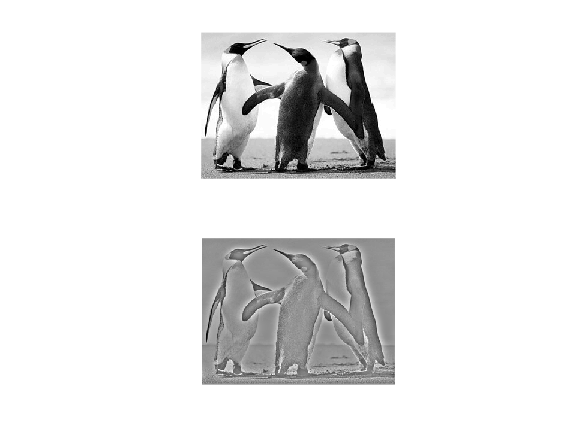

% Butterworth High Pass Filter	
[M, N] = size(input_image);
FT_img = fft2(double(input_image));
n = 2; 
D0 = 10; 
u = 0:(M-1);
v = 0:(N-1);
idx = find(u > M/2);
u(idx) = u(idx) - M;
idy = find(v > N/2);
v(idy) = v(idy) - N;
[V, U] = meshgrid(v, u);
D = sqrt(U.^2 + V.^2);
H = 1./(1 + (D0./D).^(2*n));
G = H.*FT_img;
output_image = real(ifft2(double(G)));
subplot(2, 1, 1), imshow(input_image),
subplot(2, 1, 2), imshow(output_image, [ ]);

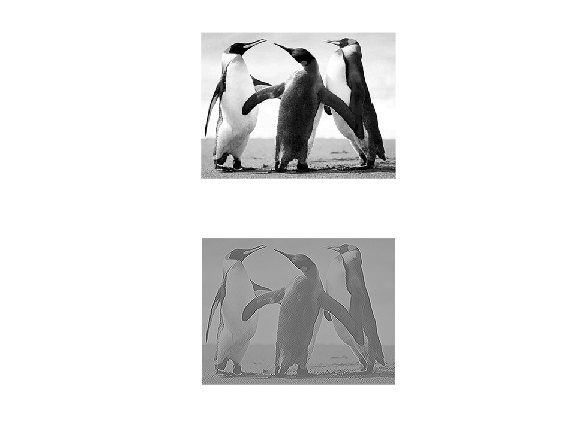

%Gaussian High Pass Filter
[M, N] = size(input_image);

FT_img = fft2(double(input_image));
n = 2; 

D0 = 20; 

u = 0:(M-1);
v = 0:(N-1);
idx = find(u < M/2);
u(idx) = u(idx) - M;
idy = find(v < N/2);
v(idy) = v(idy) - N;
 
[V, U] = meshgrid(v, u);

D = sqrt(U.^2 + V.^2);
  
H = 1./(1 + (D./D0).^(2*n));
G = H.*FT_img;
  
output_image = real(ifft2(double(G))); 
    
subplot(2, 1, 1), imshow(input_image), 
subplot(2, 1, 2), imshow(output_image, [ ]);